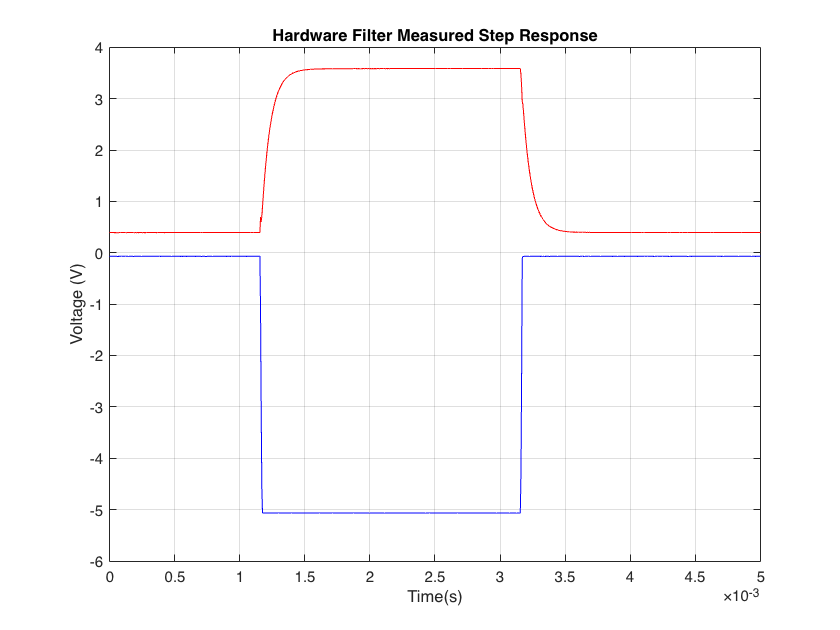

file='/Users/madi/Documents/GitHub/MATLAB/Final Project/Milestone 2/Milestone 2 Data.txt';
fileID=fopen(file);
data=textscan(fileID, '%s %s %s %s','Delimiter','\t');
fclose(fileID);

w=0:0.000005:0.005;

data1=data{1,2};
data1=str2double(data1);
data1=data1(5:1005);
data2=data{1,4};
data2=str2double(data2);
data2=data2(5:1005);

plot(w,data1,'b')
hold on 
grid on 
plot(w,data2,'r')
% ylim([-.02 .22])

% xlim([0.0040 0.0200])
% ylim([-0.103 0.137])
title('Hardware Filter Measured Step Response');
hold on;
xlabel('Time(s)');
hold on;
ylabel('Voltage (V)');
hold on;
% xline(0.00448,'--','color','m','DisplayName','10%');
% hold on
% xline(0.00532,'-.','color','black','DisplayName','90%');
% hold on
% % yline(-0.08,'--', 'color', 'b');
% hold on
% % yline(0.08,'-.','DisplayName','Percent Overshoot=54.85%');
% hold on

% xlabel('Time (s)');
% ylabel('Voltage (V)');
% title('Exercise 6-1: Second-Order Bessel Filter');
% 
% legend
hold off



% annotation('line',[0.1571 0.1304],[0.18 0.1762])
% annotation('line',[0.1571 0.1571],[0.1847 0.1071])
% annotation('line',[0.2018 0.2036],[0.7371 0.1048])
% annotation('line',[0.2018 0.1214],[0.7419 0.7405])
maxOvershoot61=max(data2)

maxOvershoot61 = 3.5887